# Labeling and Visualizing Coins

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

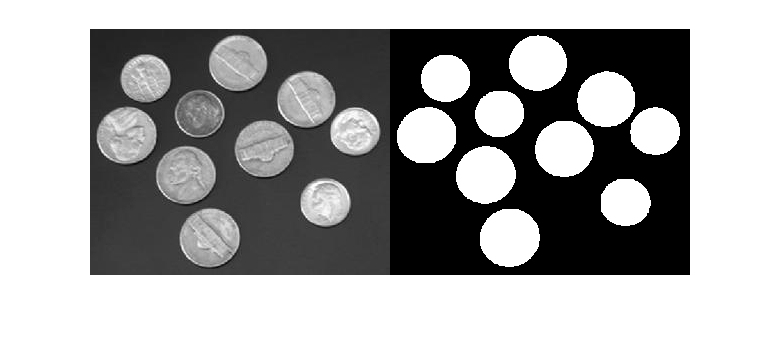

coins = imread("./images/coins.jpg");
coinsMask = imbinarize(coins);
coinsMask = imfill(coinsMask, "holes");
imshowpair(coins, coinsMask, "montage")

## Task 1

coinsCC = bwconncomp(coinsMask)

coinsCC = struct with fields:
    Connectivity: 8
       ImageSize: [246 300]
      NumObjects: 10
    PixelIdxList: {[2643×1 double]  [1851×1 double]  [2691×1 double]  [1804×1 double]  [2757×1 double]  [2522×1 double]  [2608×1 double]  [2545×1 double]  [1883×1 double]  [1865×1 double]}


## Task 2

You can create a label matrix that assigns a different label to each connected component.

`labels` `=` `labelmatrix``(``CC``)``;`

The output is a matrix the same size as the original image. The background pixels are all 0. All of the pixels in a connected component are identified with a label.

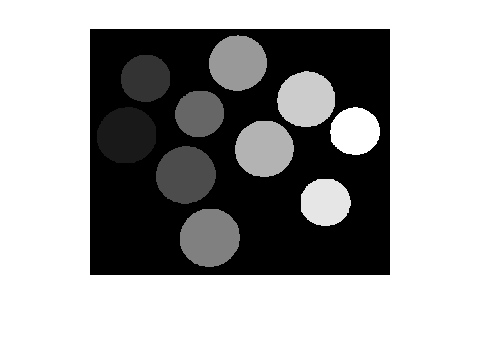

coinsLab = labelmatrix(coinsCC);
imshow(coinsLab, [])

## Task 3

If you do not use the entire display range with `[]` as a second input to `imshow`, the image looks dark because the labels range from 0 to the number of connected components.  

You can assign the components a color with `label2rgb`.

`rgb` `=` `label2rgb``(``labels``)`

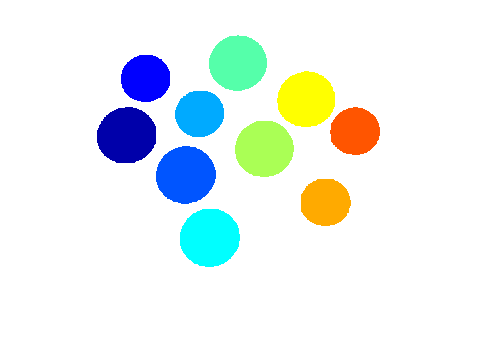

coinsRGB = label2rgb(coinsLab);
imshow(coinsRGB)

## Task 4

The colors appear to have an order from left to right. You can control this, the colormap, and the background color with additional inputs to `label2rgb`.

`rgb` `=` `label2rgb``(``labMat``,``cmap``,``bg``,``order``)``;`

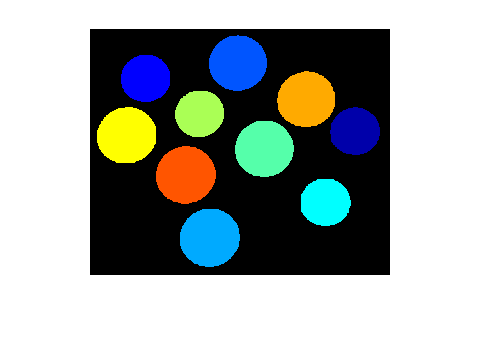

coinsRGB = label2rgb(coinsLab, "jet", "k", "shuffle");
imshow(coinsRGB)